**The simulations for the positive feedback model where mRNA activates its own degradation. **

**For Figure S1b and c.**

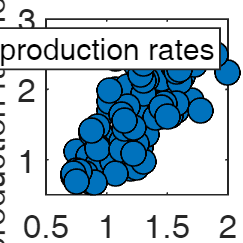

%%% Perturb mRNA production

bm=1;

syms cm
vpro=rand(1,100)*3000+1000;
vdeg=bm*cm^2;

kn_res=zeros(1,length(vpro));
cm_res=zeros(1,length(vpro));
for i=1:length(vpro)

    eq=vdeg==vpro(i);
    temp1=solve(eq,cm);
    temp2=double(temp1);
    temp3=temp2(temp2>0);

    cm_res(i)=poissrnd(temp3);%noise
    kn_res(i)=vpro(i)+normrnd(0,(vpro(i)*0.003)^2);%noise
end




%plot (Figure S1b)
colors=["#0072BD"
    "#D95319"
    "#EDB120"
    "#7E2F8E"
    "#77AC30"
    "#4DBEEE"
    "#A2142F"
    '#FF0000'
    '#00FF00'
    '#0000FF'
    '#00FFFF'
    '#FF00FF'
    '#FFFF00'
    '#000000'
    '#FFFFFF'];

fig=figure;
set(fig,'Position',[300 100 700 700]);
ax1=axes('position', [0.19 0.2 0.75 0.72]);

p1=plot(cm_res/40,kn_res/1500, ...
    'o', ...
    "MarkerSize",15, ...
    "MarkerEdgeColor",'black',...
    "LineWidth",1,...
    "MarkerFaceColor",colors(1), ...
    "DisplayName","Perturbe production rates");
xlim([0.5,2])
ylim([0.5,3])
set(ax1,'LabelFontSizeMultiplier',1.2,'linewidth',1);
set(gca,'FontSize',20)
legend(p1)
ylabel('mRNA production rate fold change','interpreter','tex','FontSize',20);
xlabel('mRNA concentration fold change','interpreter','tex','FontSize',20);

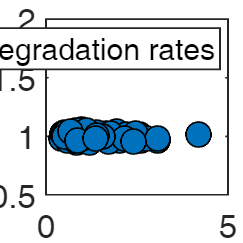

%%% Perturb mRNA degradation

bm=rand(1,100)*4;

syms cm
vpro=3000;

kn_res=zeros(1,length(bm));
cm_res=zeros(1,length(bm));
for i=1:length(bm)
    vdeg=bm(i)*cm^2;

    eq=vdeg==vpro;
    temp1=solve(eq,cm);
    temp2=double(temp1);
    temp3=temp2(temp2>0);

    cm_res(i)=poissrnd(temp3);%noise
    kn_res(i)=vpro+normrnd(0,(vpro*0.003)^2);%noise
end




%plot (Figure S1c)
colors=["#0072BD"
    "#D95319"
    "#EDB120"
    "#7E2F8E"
    "#77AC30"
    "#4DBEEE"
    "#A2142F"
    '#FF0000'
    '#00FF00'
    '#0000FF'
    '#00FFFF'
    '#FF00FF'
    '#FFFF00'
    '#000000'
    '#FFFFFF'];

fig=figure;
set(fig,'Position',[300 100 700 700]);
ax1=axes('position', [0.19 0.2 0.75 0.72]);

p1=plot(cm_res/40,kn_res/3000, ...
    'o', ...
    "MarkerSize",15, ...
    "MarkerEdgeColor",'black',...
    "LineWidth",1,...
    "MarkerFaceColor",colors(1), ...
    "DisplayName",'Perturbe degradation rates');
xlim([0,5])
ylim([0.5,2])
set(ax1,'LabelFontSizeMultiplier',1.2,'linewidth',1);
set(gca,'FontSize',20)
legend(p1)
ylabel('mRNA production rate fold change','interpreter','tex','FontSize',20);
xlabel('mRNA concentration fold change','interpreter','tex','FontSize',20);